# plot lift to drag ratio of several projectiles

clear; close; clc;

% define cross sectional parameters
a = [1,1,1,2];
b = [1,1,1,1];
d = 2.*(a.*b).^(1/2);
a = [1,1,1,2] ./ d;
b = [1,1,1,1] ./ d;
d = 2*(a.*b).^(1/2);

% body lengths
l = [10, 10, 20, 20];
% drag coefficients
C_D_0 = [.5, .2, .2, .2];
% roll angle
phi = 0

phi = 0

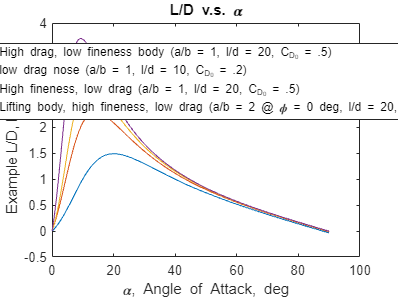


%define alphas we will ues
alpha = deg2rad(linspace(0,90,1000));

%initialize l/d ratio
LD_ratio = zeros(length(alpha),4);

%compute l/D ratios
for i = 1:length(alpha)
    LD_ratio(i,:) = lift_to_drag_ratio_body(normalForceCoeff_liftingBody(l,a,b,phi,alpha(i)), C_D_0, alpha(i));
end


plot(rad2deg(alpha), LD_ratio); title("L/D v.s. \alpha"); xlabel("\alpha, Angle of Attack, deg"); ylabel("Example L/D, Lift/Drag"); legend(["High drag, low fineness body (a/b = 1, l/d = 20, C_{D_{0}} = .5)", "low drag nose (a/b = 1, l/d = 10, C_{D_{0}} = .2)", "High fineness, low drag (a/b = 1, l/d = 20, C_{D_{0}} = .5)", "Lifting body, high fineness, low drag (a/b = 2 @ \phi = 0 deg, l/d = 20, C_{D_{0}} = .2)"], "Location","best")